# Interpolazione di Newton

Si chiama differenza divisa di f(x) relativa ai nodi $x_{0\;} ,x_1$la quantità:

$f\left\lbrack x_{0\;} ,x_1 \right\rbrack =\frac{f\left(x_0 \right)-f\left(x_1 \right)}{x_{0\;} -x_1 }=f\left\lbrack x_1 ,x_0 \right\rbrack$ in pratica è un rapporto incrementale.

Si chiama differenza divisa di ordine 2 di *f*(*x*) relativa agli argomenti *x*0, *x*1, *x*2 la quantità: $f\left\lbrack x_{0\;} ,x_1 ,x_2 \right\rbrack =\frac{f\left\lbrack x_2 ,x_1 \right\rbrack -f\left\lbrack x_1 ,x_0 \right\rbrack }{x_2 -x_0 }=f\left\lbrack x_2 ,x_1 ,x_0 \right\rbrack$

Detta differenza divisa di ordine 0 relativa all’argomento *x*0 di *f *(*x*) la quantità *f *[*x*0] = *f *(*x*0), si definisce differenza divisa di ordine *m *(*m ≥ *1) di *f *(*x*) relativa a *m *+ 1 argomenti *x*0, *x*1, . . . , *xm.*

Le differenze divise sono funzioni simmetriche dei loro argomenti, ossia se ($i_0 ,i_1 ,\ldotp \ldotp ,i_n$) è una permutazione di (0,1,...,n), allora 


$$f\left\lbrack x_{i_0 } ,x_{i_1 } ,\ldotp \ldotp \ldotp ,x_{i_n } \right\rbrack =f\left\lbrack x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_n \right\rbrack$$


La differenza divisa di ordine *n f *[*x, **x*0,* ... , **x**n**-*1] di un polinomio di grado *n *è una costante; le differenze divise di ordine maggiore di *n *sono nulle.  

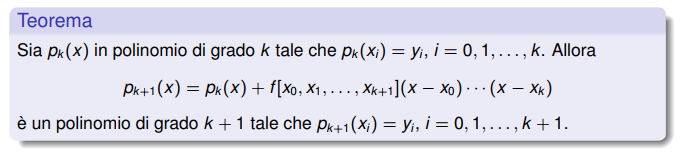

Ciò vuol dire che posso scrivere il polinomio di ordine n+1 soomando al polinomio di grado n la differenza divisa di grado n+1 moltiplicato per i relativi (x-$x_i$) con i=0,1,...,n

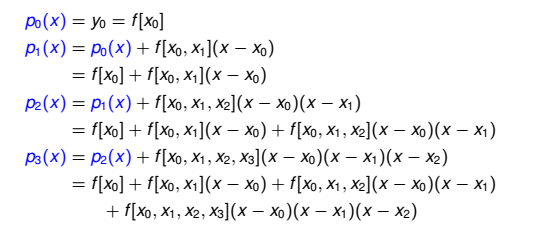

Possiamo definire $\omega \left(x\right)=\prod_{i=0}^n \left(x-x_i \right)$. Useremo quest'omega per il calcolo dell'errore del polinomio di Newton.

Poiché il polinomio di interpolazione di grado al più *n *è unico, il **polinomio di Newton **è il polinomio di interpolazione di *f*(*x*) in *x*0,...,*x**n*.

I punti *x*0, *x*1,..., *x**n *possono essere ordinati in modo arbitrario.  

L'errore di interpolazione per Newton è definito come: 


$$\frac{f^{\left(n+1\right)} \left(\xi \right)}{\left(n+1\right)!}=f\left\lbrack x,x_0 ,x_1 ,{\ldotp \ldotp \ldotp ,x}_n \right\rbrack$$


x=linspace(1,5,5)'

x =      1
     2
     3
     4
     5


y=x;
disp(tabDiff(x,y))

     1
     1
     0
     0
     0



function [d] = tabDiff(x, y)
% TABDIFF - Tabella delle differenze divise sui nodi x e i valori y
n = length(x);
d = y;
for k = 2 : n
d(k:n) = ( d(k:n) - d(k-1:n-1) ) ./ ( x(k:n) - x(1:n-k+1) );
end
end